# `Complex Longitudinal Vehicle Modeling and Estimation with LTI Systems`

`Simulink & Matlab`

`Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student `

`8/8/23`

` Ohio State University`

`with use of Robust Controls of Mechatronic Systems by Dr. Levent Guvenc`

`This is the last part of the plant derivations!`

## Combining simulation data

clc; clear; close all;
load('vehicleCellsAcceleration')
load('vehicleCellsBrake')

simCells = [vehicleCellsAcceleration,vehicleCells];

## Estimating all the sims as LTI transfer functions 

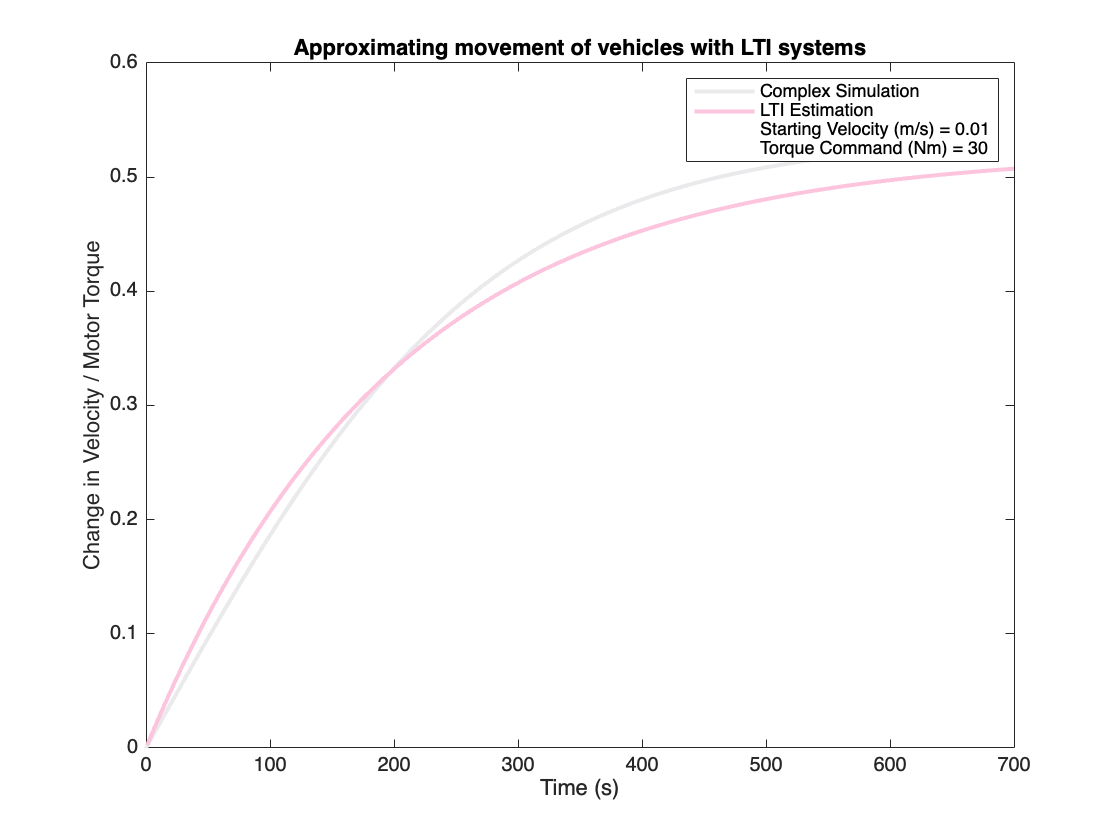

params =     0.5228  198.4711
    0.5381  111.1266
    0.4833   85.9367
    0.4378   71.7849
    0.4020   62.7987
    0.3734   57.0242
    0.3499   52.4285
    0.3629  172.7044
    0.4475  102.9433
    0.4209   80.4583


rmse_list =     0.0132
    0.0109
    0.0091
    0.0078
    0.0071
    0.0064
    0.0059
    0.0093
    0.0089
    0.0080


[params,rmse_list] = estimateLTI4(simCells,1)

## Extracting Scheduling variables and other interesting summary statistics of each simulation. 

[avg_acc,dtime,Xs,Xe,Vs,Ve,As,Ae,Tm,Tb] = getSummaryStateVars(simCells);

## Make a Table out of the results

names = {'Vs','Tm_Tb','K','T','rmse','time','avg_acc','dX','Ve','Tm','Tb'};
longitudinalModelData80823 = table(Vs',Tm'-Tb',params(:,1),params(:,2),rmse_list,dtime',avg_acc',Xe'-Xs',Ve',Tm',Tb', 'VariableNames', names)

longitudinalModelData80823 = 107×11 table
     Vs     Tm_Tb       K          T          rmse       time     avg_acc       dX        Ve      Tm     Tb
    ____    _____    ________    ______    __________    ____    _________    ______    ______    ___    __

       0       0      0.52277    198.47      0.013211      0             0         0         0      0    0 
    0.01      55      0.53809    111.13      0.010918    600      0.049325     14695    29.605     55    0 
    0.01      80      0.48331    85.937     0.0091168    600      0.064442     20125    38.675     80    0 
    0.01     105      0.43781    71.785    

# **Future Work **

**The next steps are to use these plant parameteres in a control system, and to schedule which plant is used based on the current velocity and the desired motor or brake torque. **

# **Functions **

function colors = getColors()
    a = "#0A0A0A"; % night
    %b = "#131315"; % night 
    %c = "#1D1D20"; % eerie black
    d = "#27272B"; % raisin black
    %e = "#303036"; % jet
    %f = "#3A3A41"; % onyx
    g = "#43434C"; % onyx
    %h = "#565661"; % davy"s gray
    %i = "#60606C"; % dim gray
    j = "#696977"; % dim gray
    %k = "#737382"; % slate gray
    l = "#7D7D8C"; % taupe gray
    m = "#93939F"; % cool gray
    n = "#A9A9B2"; % french gray
    o = "#BEBEC5"; % french gray
    p = "#D4D4D9"; % platinum
    q = "#EAEAEC"; % anti-flash white

    colors = [q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a]; 
end     

function colors = getColors2()
    a = "#F91079"; 
    d = "#F92484"; 
    g = "#FA388F"; 
    j = "#FA4C9A"; 
    l = "#FB60A6"; 
    m = "#FB74B1"; 
    n = "#FB88BC"; 
    o = "#FB9DC7"; 
    p = "#FCB1D2"; 
    q = "#FDC4DD"; 

    colors = [q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a]; 
end 

function [avg_acc,dtime,Xs,Xe,Vs,Ve,As,Ae,Tm,Tb] = getSummaryStateVars(simCells)
n = length(simCells(1,:));
avg_acc=zeros(1,n); dtime=zeros(1,n); Xs=dtime; Xe=dtime; Vs=dtime; Ve=dtime; As=dtime; Ae=dtime; Tm = dtime; Tb = dtime; 
    for i = 2:1:n
        % fetching the variables 
        dtime(i) = max(simCells{i}.time)-min(simCells{i}.time);
        Vs(i) = simCells{i}.V(1); Ve(i) = simCells{i}.V(length(simCells{i}.V));
        avg_acc(i) = (Ve(i)-Vs(i))/dtime(i);

        Xs(i) = simCells{i}.X(1); Xe(i) = simCells{i}.X(length(simCells{i}.X));  
        As(i) = simCells{i}.A(1); Ae(i) = simCells{i}.A(length(simCells{i}.A));
        Tm(i) = simCells{i}.Tm(length(simCells{i}.Tm));
        Tb(i) = simCells{i}.Tb(1);
    end 
end 





function [params, rmse_values] = estimateLTI4(simCells, shouldPlot)
    p = [];
    % Define constants
    e = 2.71828;
    n = length(simCells);
    params = zeros(n, 2);
    rmse_values = zeros(n, 1); % Initializing the RMSE values array

    % Check for plotting
    if shouldPlot == 1
        colors = getColors();
        colors2 = getColors2();
    end

    for i = 1:n
        % Retrieve sim data
        time = simCells{i}.time;
        V = simCells{i}.V;
        Tm = simCells{i}.Tm;
        Tb = simCells{i}.Tb;
    
        % Check for potential division by zero
        diffT = Tm - Tb;
        if any(diffT == 0)
            error('Division by zero detected. Check Tm and Tb values.');
        end

        y = (V-V(1)) ./ diffT;

        l = length(time);

        if V(1)/Tm(1) < V(l)/Tm(l) % increasing system
            peak_value = max(y);
        elseif V(1)/Tm(1) > V(l)/Tm(l) % decreasing system
            peak_value = min(y);
        else
            %('System is neither increasing nor decreasing. Check V and Tm values.');
            peak_value = max(y);
        end

        % Find the time at which the response is 63% of the peak value
        [~, index] = min(abs(y - 0.632 * peak_value));
        t_63 = time(index);

        K = peak_value;
        T = t_63;

        params(i, :) = [K, T];

        % Calculate predicted response based on estimated parameters
        predicted_response = K * (1 - e.^(-time/T));
        % Calculate RMSE for this set of data
        residuals = y - predicted_response;
        rmse = sqrt(mean(residuals.^2));
        rmse_values(i) = rmse;

        if shouldPlot == 1
            color = colors(i);
            color2 = colors2(i);
            
            % The Simulation
            p = plot(time, y, 'Linewidth', 2, 'Color', color);
            hold on;

            % Time domain 
            timeDomain = 1:1:700;
            velocity = K * (1 - e.^(-timeDomain/T)); % step response at (Tm-Tb)
            plot(timeDomain, velocity, 'Linewidth', 2, 'Color', color2);
            xlabel('Time (s)'), ylabel('Change in Velocity / Torque command'),title('Approximating movement of vehicles with LTI systems')
            startVelocity = V(1);
            torqueCommand = Tm(1) - Tb(1);
            plot(0,0,'bo','MarkerSize',0.1), plot(0,0,'ro','MarkerSize',0.1)
            legend('Complex Simulation','LTI Estimation',['Starting Velocity (m/s) = ' num2str(startVelocity)], ['Torque Command (Nm) = ' num2str(torqueCommand)]);
            drawnow
            hold off;
        end 
    end
end